Intro y bibliotecas

close all
clear all
clc
rng default;


Definir variables y crear matriz de ceros

n = 256;
num_nodos = 16;
indices_nodos = zeros(n);

Generar y graficar puntos aleatorios

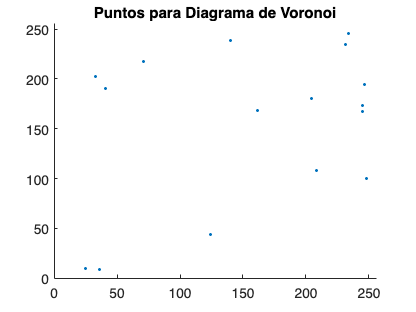

nodos = rand(num_nodos, 2) * n;

scatter(nodos(:,1), nodos(:,2), 50, '.');
axis([0 n 0 n]);
title('Puntos para Diagrama de Voronoi');

Escanear cada pixel para determinar cual es el nodo más cercano

for i = 1:n
    for j = 1:n
        distancias = sqrt(sum((nodos - [i, j]).^2, 2));
        % el simbolo ~ con la funcion min permite guardar el índice del nodo que está más cerca
        [~, indice] = min(distancias);
        indices_nodos(i, j) = indice;
    end
end


Crear una matriz de colores para cada nodo

colores_nodos = rand(num_nodos, 3);

Verificar pixel por pixel cual es el punto más cercano y asignarle el color correspondiente

mapa_colores = zeros(n, n, 3);
for i = 1:num_nodos
    indices = (indices_nodos == i);
    mapa_colores(:,:,1) = mapa_colores(:,:,1) + indices * colores_nodos(i, 1);
    mapa_colores(:,:,2) = mapa_colores(:,:,2) + indices * colores_nodos(i, 2);
    mapa_colores(:,:,3) = mapa_colores(:,:,3) + indices * colores_nodos(i, 3);
end

Pintar los poligonos de colores

figure;
imshow(mapa_colores);
title('Diagrama de Voronoi');